downloadFolder = matlab.internal.examples.downloadSupportFile("audio","ptdb-tug.zip");
dataFolder = tempdir;
unzip(downloadFolder,dataFolder)
dataset = fullfile(dataFolder,"ptdb-tug");

ads = audioDatastore([fullfile(dataset,"SPEECH DATA","FEMALE","MIC"),...
                      fullfile(dataset,"SPEECH DATA","MALE","MIC")], ...
                     IncludeSubfolders=true, ...
                     FileExtensions=".wav");

ads.Labels = extractBetween(ads.Files,"mic_","_");
countEachLabel(ads)

ans = 20×2 table
    Label    Count
    _____    _____

     F01      236 
     F02      236 
     F03      236 
     F04      236 
     F05      236 
     F06      236 
     F07      236 
     F08      234 
     F09      236 
     F10      236 
     M01      236 
     M02      236 
     M03      236 
     M04      236 
     M05      236 
     M06      236 


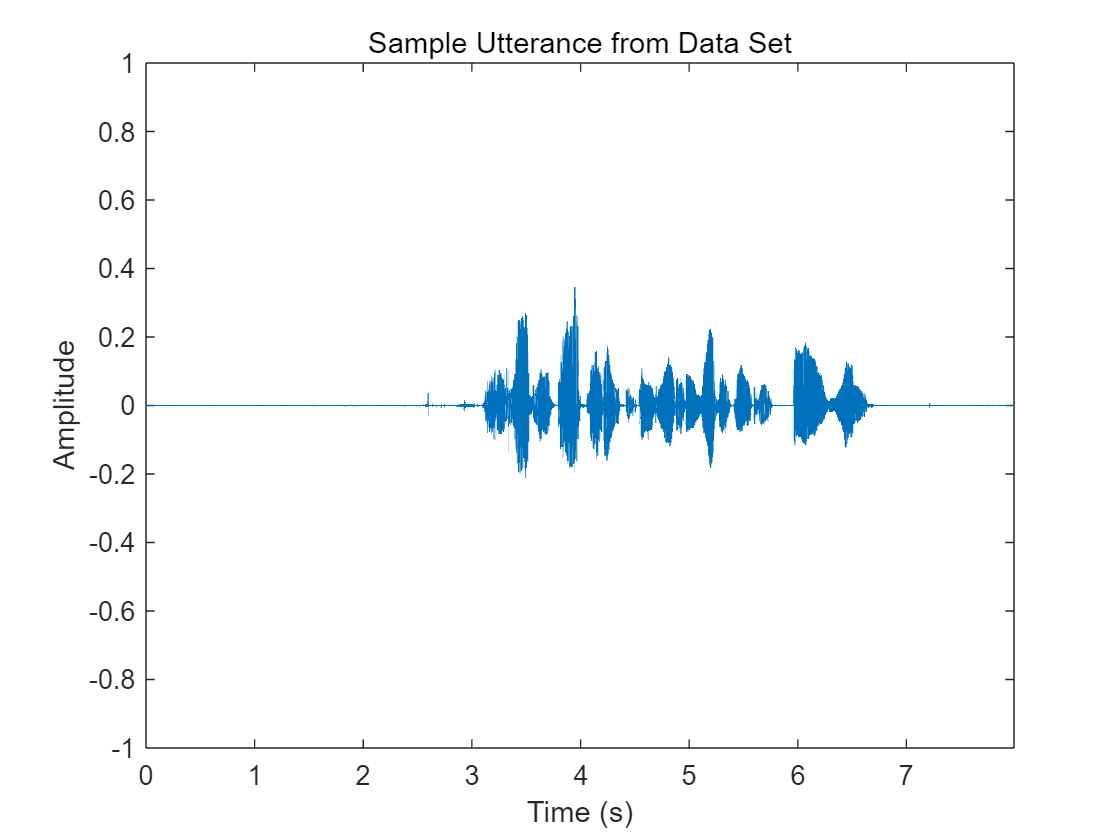

[audioIn,audioInfo] = read(ads);
fs = audioInfo.SampleRate;

t = (0:size(audioIn,1)-1)/fs;
% sound(audioIn,fs)
plot(t,audioIn)
xlabel("Time (s)")
ylabel("Amplitude")
axis([0 t(end) -1 1])
title("Sample Utterance from Data Set")

speakersToTest = categorical(["M01","M05","F01","F05"]);

adsTrain = subset(ads,~ismember(ads.Labels,speakersToTest));

ads = subset(ads,ismember(ads.Labels,speakersToTest));
[adsEnroll,adsTest,adsDET] = splitEachLabel(ads,3,1);

countEachLabel(adsTrain)

ans = 16×2 table
    Label    Count
    _____    _____

     F02      236 
     F03      236 
     F04      236 
     F06      236 
     F07      236 
     F08      234 
     F09      236 
     F10      236 
     M02      236 
     M03      236 
     M04      236 
     M06      236 
     M07      236 
     M08      236 
     M09      236 
     M10      236 


countEachLabel(adsEnroll)

ans = 4×2 table
    Label    Count
    _____    _____

     F01       3  
     F05       3  
     M01       3  
     M05       3  


countEachLabel(adsTest)

ans = 4×2 table
    Label    Count
    _____    _____

     F01       1  
     F05       1  
     M01       1  
     M05       1  


countEachLabel(adsDET)

ans = 4×2 table
    Label    Count
    _____    _____

     F01      232 
     F05      232 
     M01      232 
     M05      232 


speakerVerification = ivectorSystem(SampleRate=fs)

speakerVerification =   ivectorSystem - 属性:

         InputType: 'audio'
        SampleRate: 48000
      DetectSpeech: 1
           Verbose: 1
    EnrolledLabels: [0×2 table]


trainExtractor(speakerVerification,adsTrain, ...
    UBMNumComponents=128,UBMNumIterations=5, ...
    TVSRank=64,TVSNumIterations=3)

Calculating standardization factors ....done.
Training universal background model ........done.
Training total variability space ....


错误使用  \ 
矩阵接近奇异值，或者缩放不良。结果可能不准确。RCOND =  2.010268e-16。

出错 audio.internal.ivector.ds.trainTVS>accumulateStatistics (第 251 行)
Ey = temp\(TtimesInverseSSdiag*F(:));

出错 audio.internal.ivector.ds.trainTVS (

trainClassifier(speakerVerification,adsTrain,adsTrain.Labels, ...
    NumEigenvectors=16, ...
    PLDANumDimensions=16,PLDANumIterations=3)